# Liquidity Pool Simulation

The code below implements a simulation for a liquidity pool with a constant product formula.

## Initialization

% token names
T_a = Token("GenericToken");
T_b = Token("USDC");

% token initial balances
init_Q_a = 1000000;
init_Q_b = 1000000;

% liquidity pool fee
fee = 0.003;

% volatility (constant)
sigma = 10;

% number of iterations for the simulations
n = 2000;

## Simulation

[Q_a, Q_b, P_a, K, sellProb] = simulateLiquidityPool(n, T_a, T_b, init_Q_a, ...
                                           init_Q_b, fee, sigma);

## Plot results

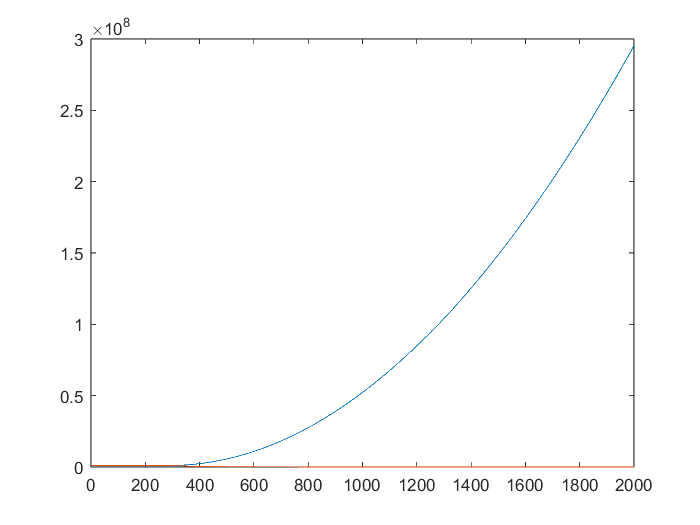

plot(Q_a);
hold on;
plot(Q_b);
xlim([0 n]);
hold off;

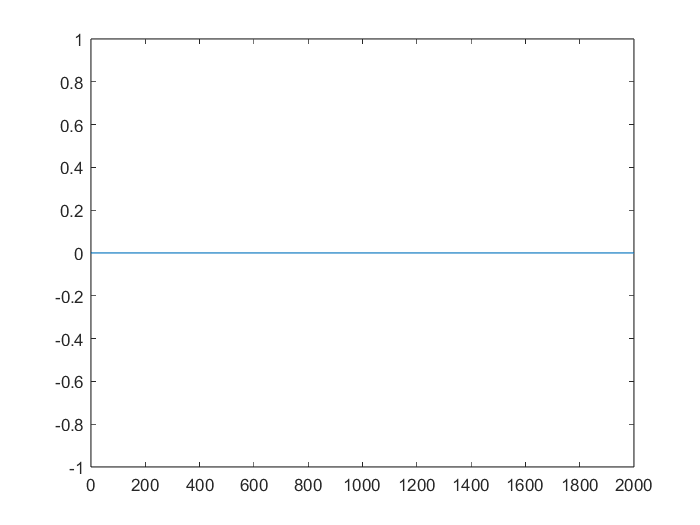


plot(sellProb);
xlim([0 n]);

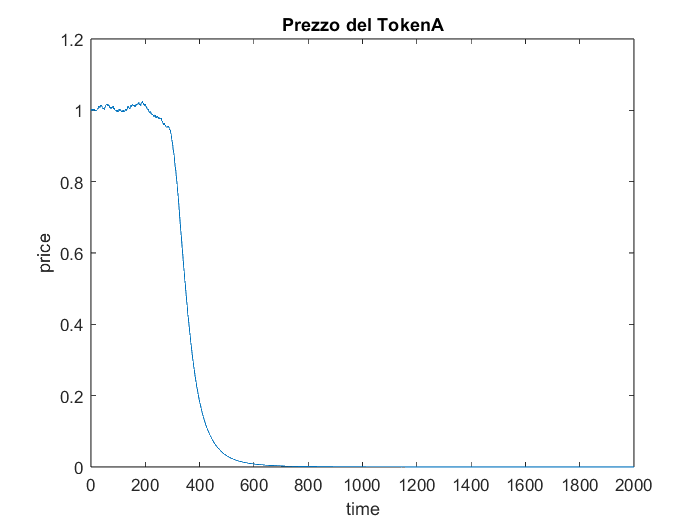


plot(P_a);
title("Prezzo del TokenA");
xlabel("time");
ylabel("price");
xlim([0 n]);

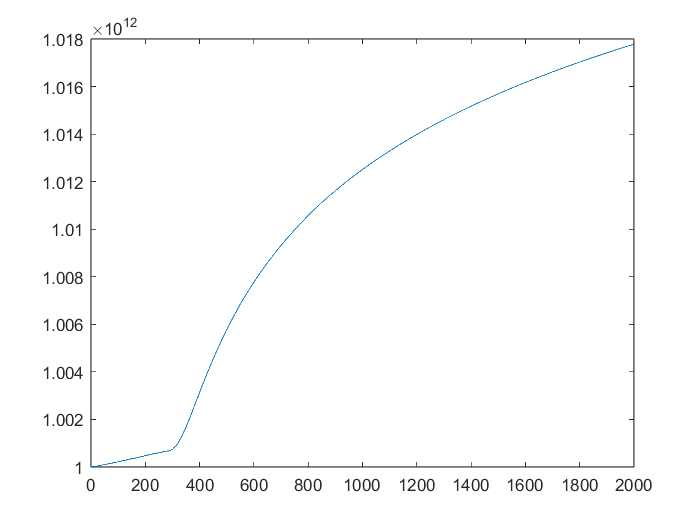


plot(K); 
xlim([0 n]);

## Verify central limit theorem

#### Initialization

n = 1000;
m = 1000;
finalPrices = zeros(1, m);

#### Execution

for i = 1:m
    [Q_a, Q_b, P_a, K, sellProb] = simulateLiquidityPool(n, T_a, T_b, init_Q_a, ...
                                           init_Q_b, fee, sigma);
    finalPrices(i) = P_a(n + 1);
end

#### Plot result

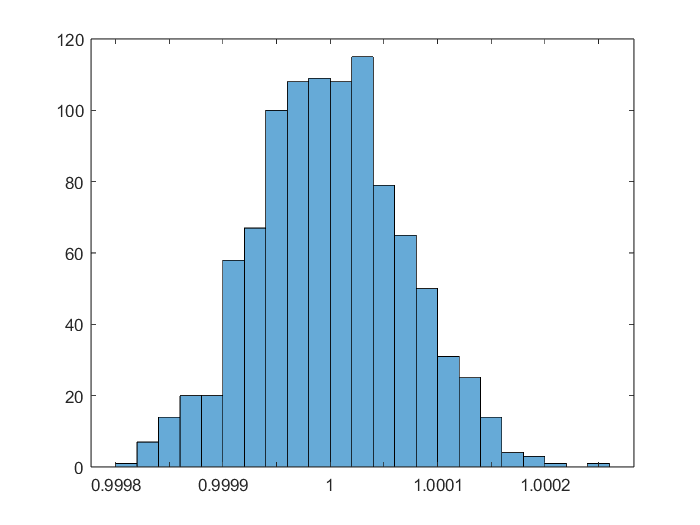

histogram(finalPrices);